# **Implementing a novel gain stage to the filter**

## **Idea**

The Moog LPF, like other LPFs, attenuates the high-frequency content of the incoming signal in[n] beyond the passband & outputs y[n].

However, the signal energy is removed, thus reducing the overall signal amplitude in time domain.

This project aims to implement an additional gain stage (per suggested by Daly) to the filter that 'makes up' the gain & restores signal energy.

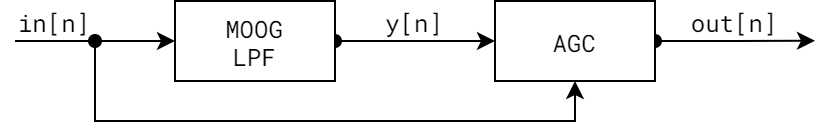

Original paper by Huovilainen [here](https://cpb-us-w2.wpmucdn.com/sites.gatech.edu/dist/e/466/files/2016/11/P_061.pdf). Original GitHub source code in C++ [here](https://github.com/ddiakopoulos/MoogLadders).

Code derived from equations per analyis by Paul Daly - see thesis [here](http://www.acoustics.ed.ac.uk/wp-content/uploads/AMT_MSc_FinalProjects/2012__Daly__AMT_MSc_FinalProject_MoogVCF.pdf).

## Preparations

close all; clear; clc;

Loads audio file of specific frequency - uses square waves for testing.

% Sets sampling frqc to audio output (44.1k Hz)
Fs = 44.1e+3;
Ts = 1/Fs;
duration = 1;
t = (0:Ts:duration);
in_audio = (t == 0);

Plots the input audio into the time domain

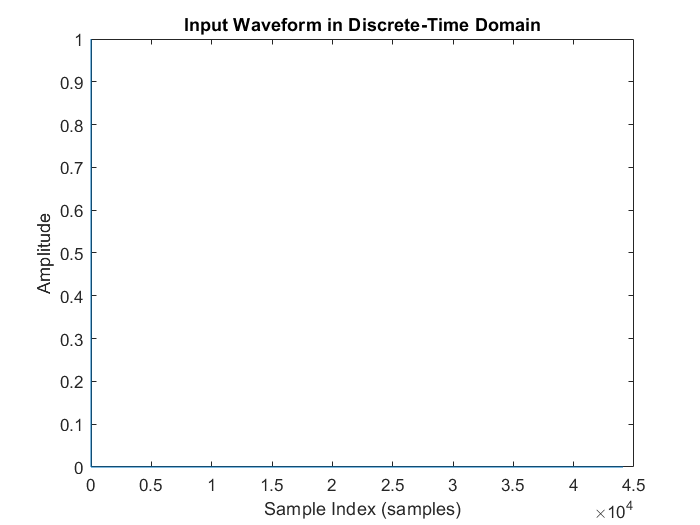

plot(in_audio);
title("Input Waveform in Discrete-Time Domain");
xlabel("Sample Index (samples)");
ylabel("Amplitude");

Before plotting numerical results we need to define the range to use for plots.

Recall the formula for sampling & frequency normalisation.


$$\Omega = 2\pi f T_s \equiv 2\pi \frac{f}{f_s} = 2\pi F$$


We defined the range of frequency to be 1:Fs. This obtains the normalised angular frequency for 0:2pi.

% NOTE: Define normalised frequency HERE
range_f = (1 : Fs/2);
% Recall that sampling results in identical peaks
% So half since we want range of 0:pi & not 0:2pi
% So given cycles/second this ranges 0:1
range_f_normalised = range_f * (2 * pi) / Fs;

Let us plot the FFT of the impulse as well.

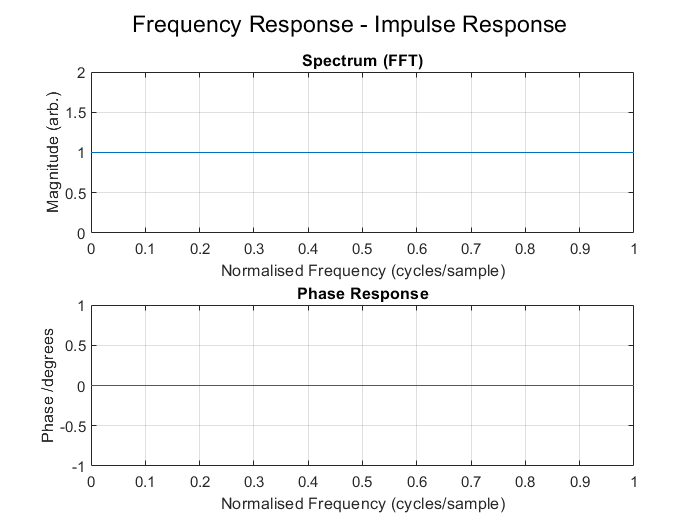

[magnt_linear_imp, phase_linear_imp] = deal(abs(fft(in_audio)), angle(fft(in_audio)));
figure;
sgtitle("Frequency Response - Impulse Response")

subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        (magnt_linear_imp(range_f)) ...
        );
title("Spectrum (FFT)");
xlabel("Normalised Frequency (cycles/sample)");
ylabel("Magnitude (arb.)");
grid on

subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        (mod( (phase_linear_imp(range_f) * 180/pi), -360 )) ...
        );
title("Phase Response");
xlabel("Normalised Frequency (cycles/sample)");
ylabel("Phase /degrees");
grid on

As an impulse, we expect a full range of frequency with magnitude 1.

Note: dB axis might not be as useful here since doing so results in "Magnitude (dB)" of 0 instead of 1 (as expected)

## Linear Moog VCF model

The transfer function of the analog Moog VCF was determined by Smith and Stilton as


$$H(s)=\frac{1}{k + \left(1 + \frac{s}{\omega_c}\right)^4}
\equiv
\left(
\frac{1}{k+
\left(\frac{1}{\omega_c^4}s^4 + \frac{4}{\omega_c^3}s^3 + \frac{6}{\omega_c^2}s^2 + \frac{4}{\omega_c}s + 1 \right)} 
\right)
\equiv
H(j\omega)=\frac{1}{k + \left(1 + \frac{j\omega}{\omega_c}\right)^4} $$


where $s=\sigma + j\omega = j2\pi f$.

The frequency responses of the model can thus be modelled for the Laplace domain.

gainFeedbk = 3.99; % Feedback gain
Fc = 100; % Cutoff frequency
Fc = 440;

We can plot the frequency response of the analogue linear model.

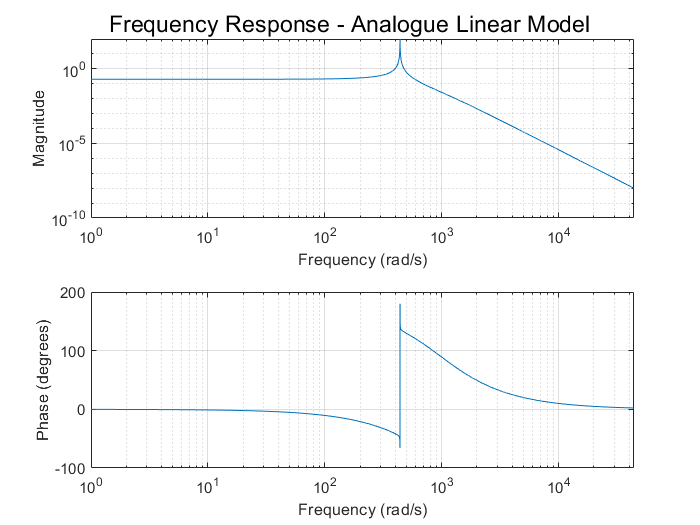

Wc = Fc;
H_num = 1;
H_den = [   (1/(Wc ^ 4)) ...
            (4/(Wc ^ 3)) ...
            (6/(Wc ^ 2)) ...
            (4/(Wc ^ 1)) ...
            (1 + gainFeedbk) ...
            ];
figure;
sgtitle("Frequency Response - Analogue Linear Model")
freqs(H_num, H_den, (1:Fs))

Let us plot the frequencies in order.

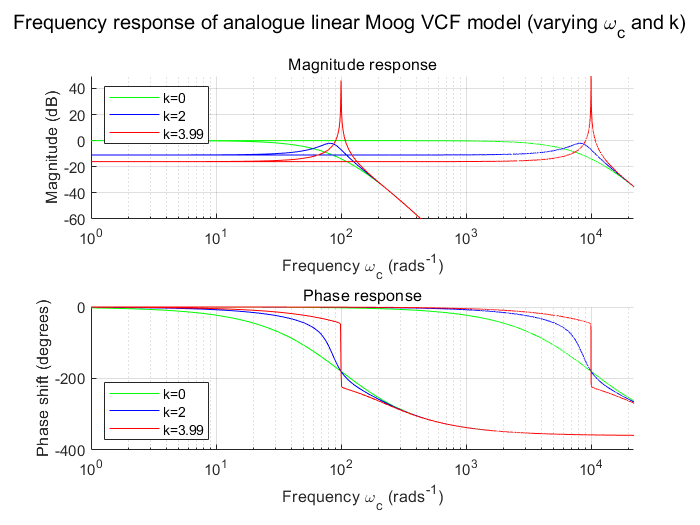

Wc = Fc;
range_gainFeedbk = [0, 2, 3.99];
ss_data_magnt = [];
ss_data_phase = [];
H_num = 1;
for i_frqc = 0:1
    wc_now = 100 * (100 ^ i_frqc);
    for i_gainFeedbk = 1:length(range_gainFeedbk)
        H_den = [   (1/(wc_now ^ 4)) ...
                    (4/(wc_now ^ 3)) ...
                    (6/(wc_now ^ 2)) ...
                    (4/(wc_now ^ 1)) ...
                    (1 + range_gainFeedbk(i_gainFeedbk)) ...
                    ];
        %freqs(H_num, H_den, (1:Fs));
        h_now = freqs(H_num, H_den, (1:Fs));
        ss_data_magnt(i_frqc+1, i_gainFeedbk, :) = abs(h_now(range_f));
        ss_data_phase(i_frqc+1, i_gainFeedbk, :) = angle(h_now(range_f));
    end
end


range_color = ['g', 'b', 'r'];
figure;
% sgtitle("Frequency Response - Analogue Linear Model (varying \omega_c and k)")
sgtitle("Frequency response of analogue linear Moog VCF model (varying \omega_c and k)", 'FontSize', 12)
% Plots magnt
subplot(2, 1, 1);
subtitle("Magnitude response") % of analogue linear Moog VCF Model (varying \omega_c and k)")
ylim([-60, inf])
set(gca, 'XScale', 'log');
xlim([0, Fs/2])
xlabel("Frequency \omega_c (rads^{-1})")
ylabel("Magnitude (dB)")
grid on
hold on
arr_plot_magnt = [];
for i_gainFeedbk = 1:length(range_gainFeedbk)
    for i_frqc = 1:2
        data_now = reshape(ss_data_magnt(i_frqc, i_gainFeedbk, :), [22050, 1, 1]);
        arr_plot_magnt(end+1) = plot(range_f, 10*log(data_now), 'color', range_color(i_gainFeedbk));
    end
end
legend(arr_plot_magnt([1, 3, 5]), {'k=0','k=2','k=3.99'}, 'Location', 'northwest')

subplot(2, 1, 2);
% Plots phase
% figure;
% sgtitle("Phase Response - Analogue Linear Model (100 to 10000)")
subtitle("Phase response") % of analogue linear Moog VCF Model (varying \omega_c and k)")
ylim([-400, 0])
set(gca, 'XScale', 'log');
xlim([0, Fs/2])
% set(gca, 'XScale', 'log');
% xlim([0, Fs/2])
xlabel("Frequency \omega_c (rads^{-1})")
ylabel("Phase shift (degrees)")
grid on
hold on
arr_plot_phase = [];
for i_gainFeedbk = 1:length(range_gainFeedbk)
    for i_frqc = 1:2
        data_now = reshape([ss_data_phase(i_frqc, i_gainFeedbk, :)  * 180 / pi], [22050, 1, 1]);
        arr_plot_phase(end+1) = plot(range_f, mod(data_now, 360)-360, 'color', range_color(i_gainFeedbk));
    end
end
legend(arr_plot_phase([1, 3, 5]), {'k=0','k=2','k=3.99'}, 'Location', 'southwest')

Let us also plot the PZ diagram

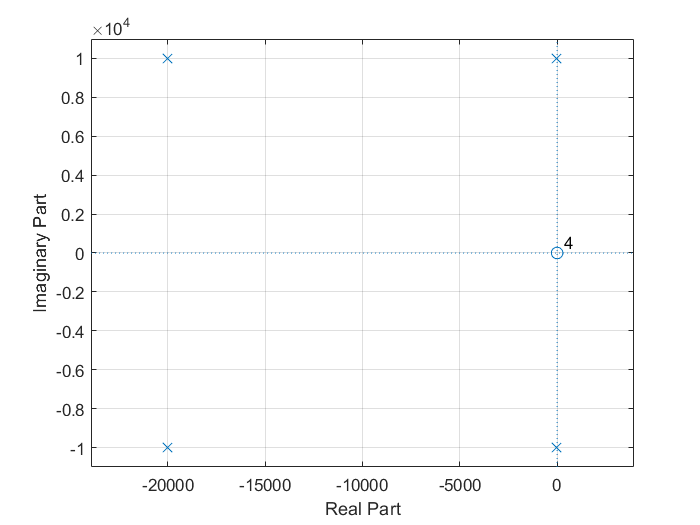

figure;
zplane(H_num, H_den)
grid on

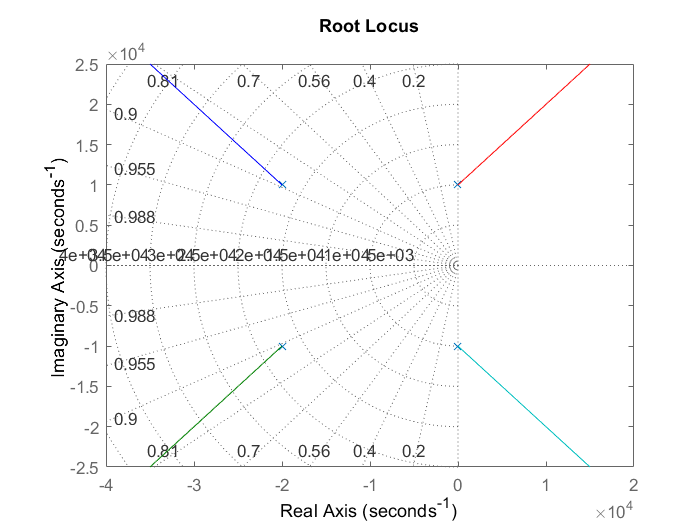

rlocus(tf(H_num, H_den))
grid on

range_gainFeedbk = [0, 1, 2, 4];
H_num = 1;
plot_pz = []


plot_pz =

     []



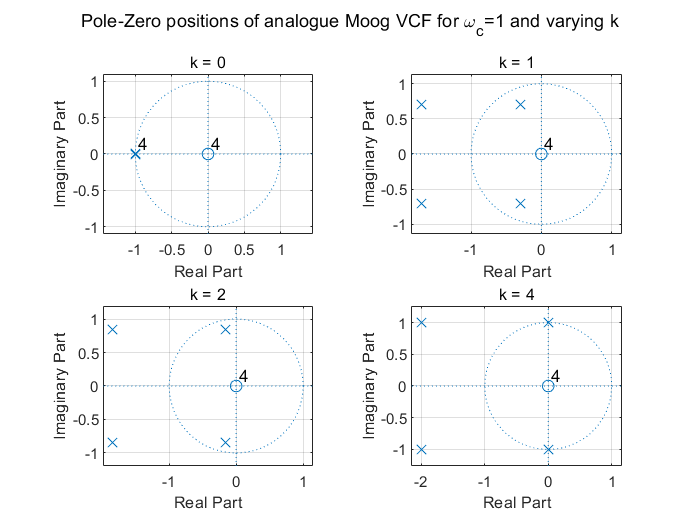

%for i_frqc = 0:1
    wc_now = 1; %100 * (100 ^ i_frqc);
    for i_gainFeedbk = 1:length(range_gainFeedbk)
        H_den = [ (1/(wc_now ^ 4)) ...
                            (4/(wc_now ^ 3)) ...
                            (6/(wc_now ^ 2)) ...
                            (4/(wc_now ^ 1)) ...
                            (1 + range_gainFeedbk(i_gainFeedbk)) ...
                            ];
        %freqs(H_num, H_den, (1:Fs));
        %h_now = freqs(H_num, H_den, (1:Fs));
        %ss_data_magnt(i_frqc+1, i_gainFeedbk, :) = abs(h_now(range_f));
        %ss_data_phase(i_frqc+1, i_gainFeedbk, :) = angle(h_now(range_f));
%         figure;
        plot_pz(end+1, :) = H_den;
%         grid on
    end

figure;
% sgtitle("Frequency Response - Analogue Linear Model (varying \omega_c and k)")
title("Pole-Zero positions of analogue Moog VCF", 'FontSize', 12)
% Plots magnt
subplot(2, 2, 1);
zplane(H_num, plot_pz(1, :));
subtitle("k = 0") 
grid on
subplot(2, 2, 2);
zplane(H_num, plot_pz(2, :));
subtitle("k = 1") 
grid on
subplot(2, 2, 3);
zplane(H_num, plot_pz(3, :));
subtitle("k = 2") 
grid on
subplot(2, 2, 4);
zplane(H_num, plot_pz(4, :));
subtitle("k = 4") 
grid on
sgtitle("Pole-Zero positions of analogue Moog VCF for \omega_c=1 and varying k", 'FontSize', 11)



%end

$H(s)$ was calculated for each integer $f$ (where $f \in [0, 22050]$).

The magnitude response of the analog filter was determined by plotting $20log_{10}|H(s)|$ across the range of $f$ - note the full-scale decibel used.

The phase angles $\angle H(s)$ was also plotted against $f$ to calculate the phase response, in this case in degrees.

## Huovilainen's Linear Models

### Unit-Delay Implementation

Huovilainen's "unit delay" implementation uses Euler's method, its iterations are defined per following, where $g=1-e^{-\omega_{c, a}/F_s}$ is the weighing coefficient, such that $\omega_{c,analog} = \frac{2}{T_s}tan\left(T_s\frac{\omega_{c,d}}{2}\right)$ is the "analog" cut-off frequency, and $\omega_{c,d}$ is the "digital" cut-off frequency set by the user.


$$y_{a}[n] = y_{a}[n-1] + g\left(x[n] - y_{a}[n-1] - ky_{d}[n-1]\right)$$



$$y_{b}[n] = y_{b}[n-1] + g\left(y_{a}[n] - y_{b}[n-1]\right)$$



$$y_{c}[n] = y_{c}[n-1] + g\left(y_{b}[n] - y_{c}[n-1]\right)$$



$$y_{d}[n] = y_{d}[n-1] + g\left(y_{c}[n] - y_{d}[n-1]\right)$$


The model can therefore be represented by the following IIR filter

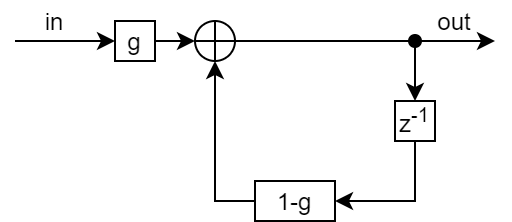

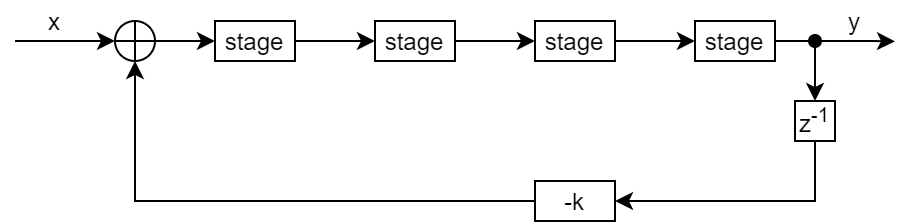

We can find the frequency response in the z-domain.


$$V_o[n] = V_o[n-1] + g( V_i[n]  - V_o[n-1])$$



$$V_o[n] = (1-g)V_o[n-1]+gV_i[n]$$



$$V_o(z)=(1-g)V_o(z)z^{-1}+gV_i(z)$$



$$H(z) :=
\frac{V_o(z)}{V_i(z)}
=
\frac{g}{1+z^{-1}(g-1)}
\equiv
\frac{1}{\left(\frac{1}{g}\right) + z^{-1} \left( 1 - \frac{1}{g} \right) }$$



$$H(z = e^{j\omega})
=
\frac{1}
{\left(\frac{1}{g}\right)
+
e^{-j\omega}{\left(1-\frac{1}{g}\right)
}$$



$$H_{s4}(z)=\frac{g^4}{(1+z^{-1}(g-1))^4}$$



$$H_{all}(z) = \frac{H_{s4}}{1+z^{-1}kH_{s4}}
\equiv
\frac{H_{s4}/k}{\frac{1}{k}+z^{-1}H_{s4}}$$


coefWeight = f_coefWeight(Fc, Fs);

Given the gain coefficient, we can plot the frequency response for each stage.

#### Analytical Results

To obtain analytical results from the transfer function in MATLAB, we define the symbolic variable.

% Defining transfer function in z-domain
z = tf('z', -1);

Here, we can define the transfer functions for all the stages.

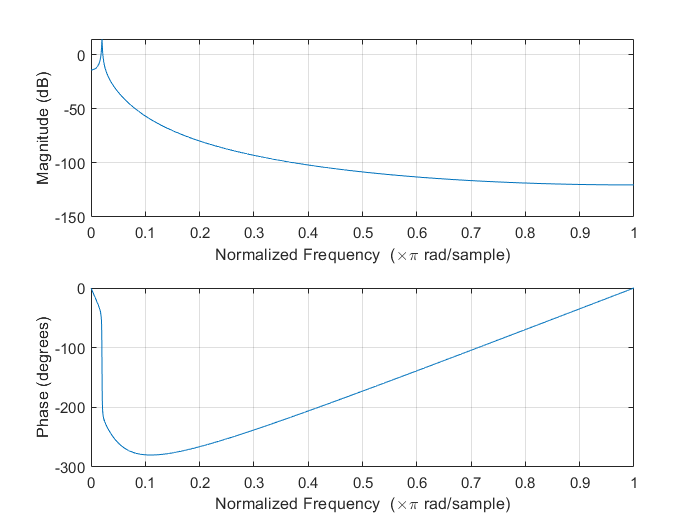

tf_1 = (coefWeight)/(1 + (z^-1 * (coefWeight - 1)));
tf_4 = tf_1 ^ 4;
tf_full_unit = (tf_4)/(1 + (z^-1 * gainFeedbk * tf_4));
[num_full_unit, den_full_unit] = tfdata(tf_full_unit);
[num_full_unit, den_full_unit] = deal(cell2mat(num_full_unit), cell2mat(den_full_unit));
figure;
sgtitle("Frequency Response - Huovilainen's Unit Delay Model (Analytical)")
freqz(num_full_unit, den_full_unit, Fs)

To find the pole placements & root loci on the z-plane, we can plot the transfer functions.

Note that in the report, this diagram MUST be cleaned up!

We can determine that the responses in frequency & z domains are identical. Note the normalised frequency range on the latter extending to pi - this is because the pi-2pi is a mirrored identical of the responses from 0-pi due to aliasing at Fs/2.

#### Numerical Results

We can plot the numerical results of the unit-delay model.

tic;
out_linear_unit = f_runFilter(in_audio, duration, Fs, coefWeight, gainFeedbk, "linear_unit");
toc;

Elapsed time is 0.022196 seconds.


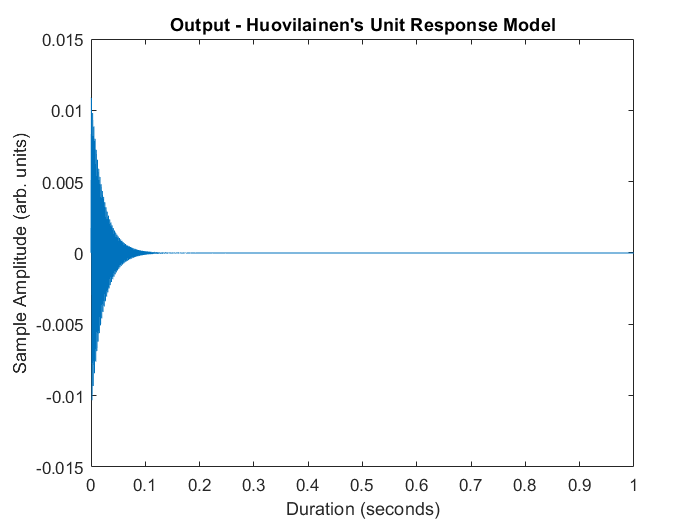

figure;
plot(t(1:end-1), out_linear_unit);
title("Output - Huovilainen's Unit Response Model");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");

We can now plot the numerical results.

NOTE: To view spectrum in normalized frequency, uncomment the lines.

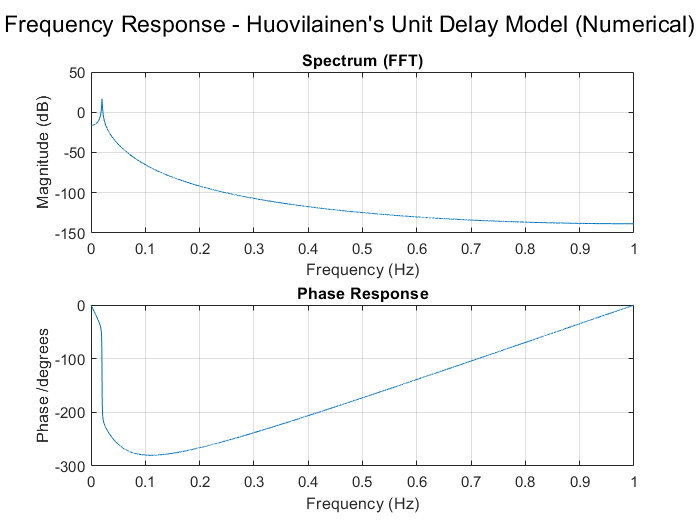

[magnt_linear_unit, phase_linear_unit] = deal(abs(fft(out_linear_unit)), angle(fft(out_linear_unit)));
figure;
sgtitle("Frequency Response - Huovilainen's Unit Delay Model (Numerical)")

subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        (10 * log(magnt_linear_unit(range_f))) ...
        );
title("Spectrum (FFT)");
% xlabel("Normalised Frequency (cycles/sample)");
xlabel("Frequency (Hz)");
ylabel("Magnitude (dB)");
grid on

subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        (mod( (phase_linear_unit(range_f) * 180/pi), -360 )) ...
        );
title("Phase Response");
% xlabel("Normalised Frequency (cycles/sample)");
xlabel("Frequency (Hz)");
ylabel("Phase /degrees");
grid on

Note the subscripts $[a,b,c,d]$ refer to the first, second, third, and fourth stages of the ladder (rising from the bottom).

Also note $x_n$ is the input sequence.

The calculations must be carried out in that specific order.

The input signal $x$ is a pulse train of $N=10^{14}$ samples.

The recursive relations are used in a loop of $N$ iterations, where each iteration stores the output $y_d$ being the filter impluse response.

The magnitude response was calculated in dBFS as $20log_10|FFT(y_d)|$, where $FFT$ is the fast Fourier transform function.

The phase angles of $y_d$ were extracted to calculate the phase response.

The magnitude & phase responses were plotted against the frequency bins of the $FFT$ where the $n^{th}$ bin equals $F_s n / N$ for $n \in [0, (N-1)]$. $N$ was chosen to be large to increase the $FFT$ resolution, and thus the plot.

### Unit-and-a-Half Delay Implementation

The "unit-and-a-half" delay is similar to the original "unit-delay" model & simply changes the first iteration.


$$y_{a}[n] = y_{a}[n-1] + g\left(x[n] - k\frac{y_{d}[n-1] + y_{d}[n-2]}{2} - y_{a}[n-1]\right)$$


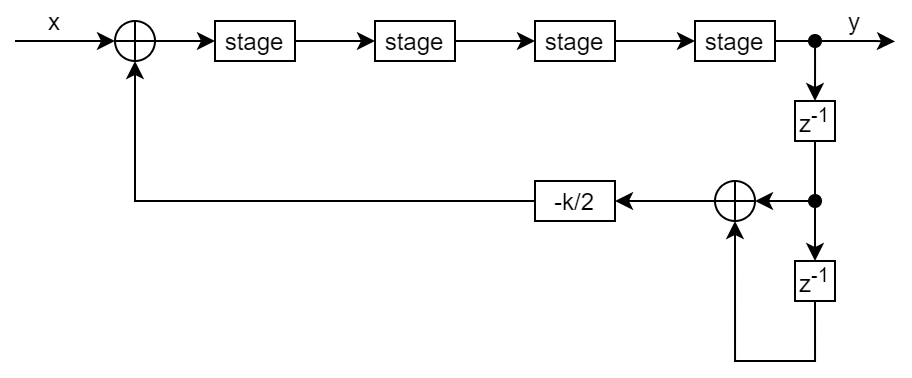


$$H_{all}(z) = \frac{H_{s4}}{1+\left(\frac{k}{2}\right)H_{s4}(z^{-1}+z^{-2})}$$


#### Analytical Results

To obtain analytical results from the transfer function in MATLAB, we use the symbolic variable from the unit delay response model.

Here, we can define the transfer functions for all the stages. Since we've defined them before, the same transfer function given single stage can be used.

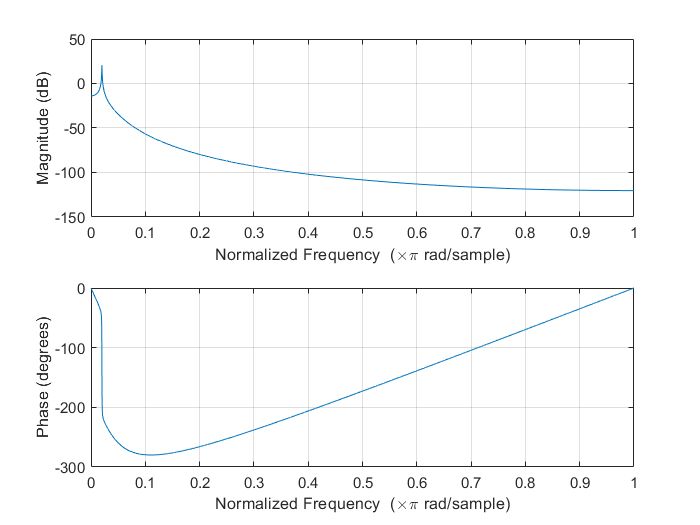


tf_full_half = (tf_4)/(1 + ((z^-1 + z^-2) * 0.5 * gainFeedbk * tf_4));
[num_full_half, den_full_half] = tfdata(tf_full_half);
[num_full_half, den_full_half] = deal(cell2mat(num_full_half), cell2mat(den_full_half));
figure;
sgtitle("Frequency Response - Huovilainen's 'Unit-and-a-Half' Delay Model (Analytical)")
freqz(num_full_half, den_full_half, Fs)

To find the pole placements & root loci on the z-plane, we can plot the transfer functions.

#### Numerical Results

tic;
out_linear_half = f_runFilter(in_audio, duration, Fs, coefWeight, gainFeedbk, "linear_half");
toc;

Elapsed time is 0.018481 seconds.


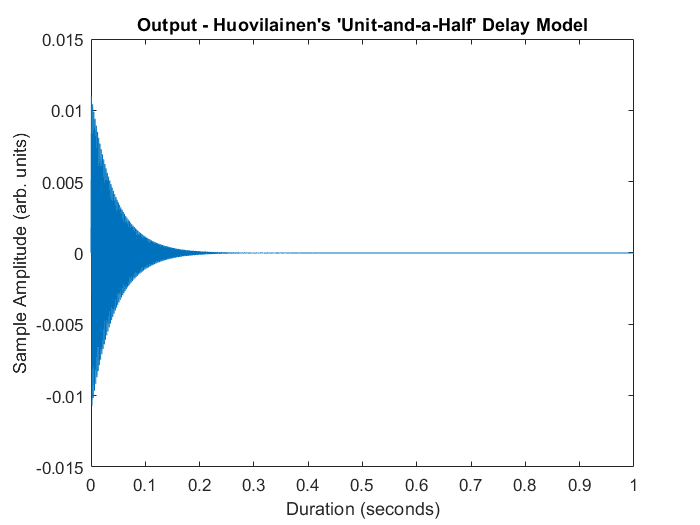

figure;
plot(t(1:end-1), out_linear_half);
title("Output - Huovilainen's 'Unit-and-a-Half' Delay Model");
xlabel("Duration (seconds)");
% xlabel("Sample Index (samples)");
ylabel("Sample Amplitude (arb. units)");

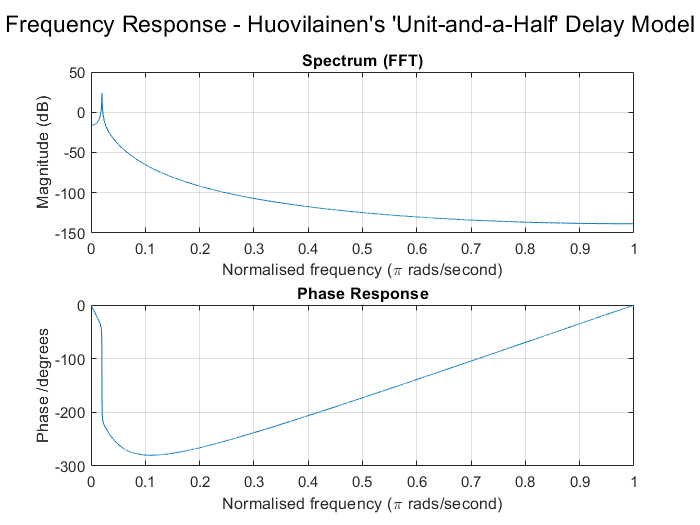

[magnt_linear_half, phase_linear_half] = deal(abs(fft(out_linear_half)), angle(fft(out_linear_half)));
figure;
sgtitle("Frequency Response - Huovilainen's 'Unit-and-a-Half' Delay Model")

subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        ( 10 * log( magnt_linear_half(range_f) ) )...
        );
title("Spectrum (FFT)");
ylabel("Magnitude (dB)");
xlabel("Normalised frequency (\pi rads/second)");
grid on

subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        ( mod(( phase_linear_half(range_f) * 180/pi ), -360) )...
        );
title("Phase Response");
ylabel("Phase /degrees");
xlabel("Normalised frequency (\pi rads/second)");
grid on

Notice the phase distortions in the output signal. This was noted in Daly's thesis.

### Tuned Unit-and-a-Half Delay Implementation

Huovilainen also used a tuning table to tune the user input to a specific frequency, such that it eliminates any remaining errors in the frequency response. These are implemented via an interpolating function, see the paper in the link.

Note that the values are only functional when $F_s = 88.2k Hz$.

Note Huovilainen states that no additional filter-tuning is required as his filter is based on the analog circuit alone.

## Huovilainen's Non-linear Models

Huovilainen's linear models presented above can be transformed to a non-linear variant.


$$y_{a}[n] = y_{a}[n-1] + g\left(tanh\left(x[n] - k\frac{y_{d}[n-1] + y_{d}[n-2]}{2}\right) - tanh(y_{a}[n-1])\right)$$



$$y_{b}[n] = y_{b}[n-1] + g\left(tanh(y_{a}[n]) - tanh(y_{b}[n-1])\right)$$



$$y_{c}[n] = y_{c}[n-1] + g\left(tanh(y_{b}[n]) - tanh(y_{c}[n-1])\right)$$



$$y_{d}[n] = y_{d}[n-1] + g\left(tanh(y_{c}[n]) - tanh(y_{d}[n-1])\right)$$


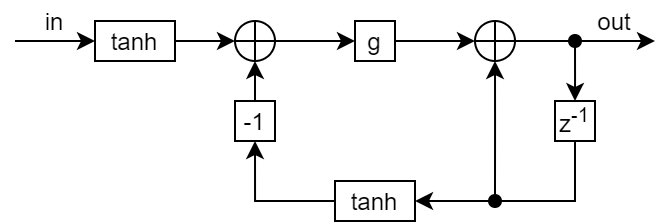

Single stage of nonlinear

The overarching 'super-stage' is the same as the unit-and-a-half delay model.

#### Numerical Results

figure;
tic;
out_nonlinear = f_runFilter(in_audio, duration, Fs, coefWeight, gainFeedbk, "nonlinear");
toc;

Elapsed time is 0.033682 seconds.


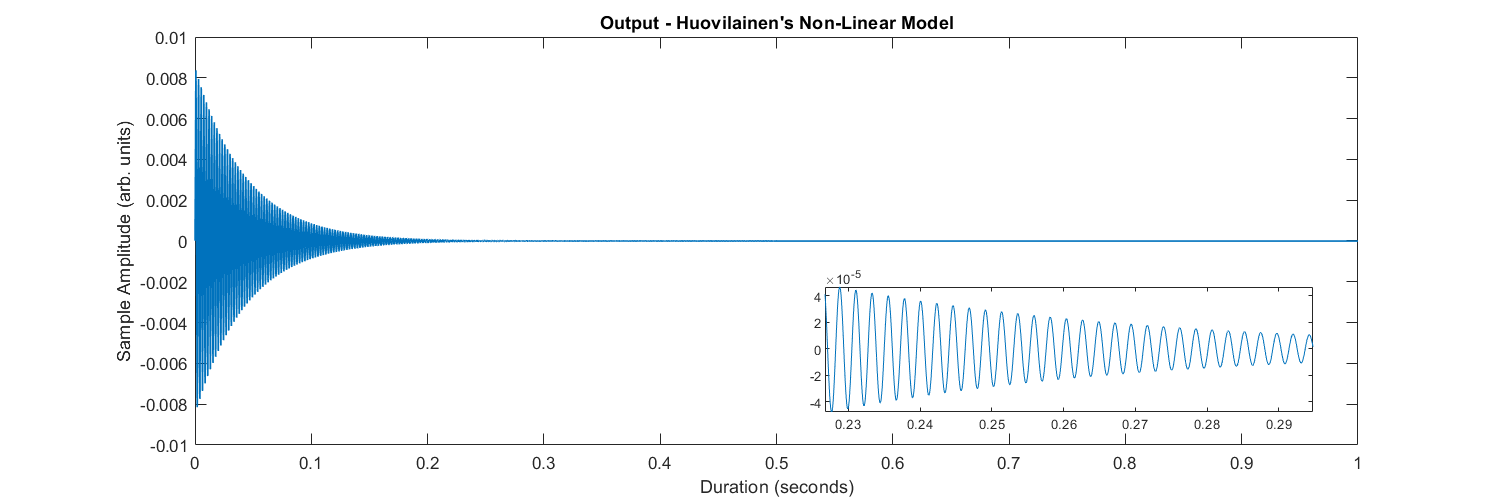

plot(t(1:end-1), out_nonlinear, 'LineWidth', 1);
title("Output - Huovilainen's Non-Linear Model");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.175 0.325 0.25])
box on % put box around new pair of axes
plot(t(10000:13000), out_nonlinear(10000:13000)) % plot on new axes
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

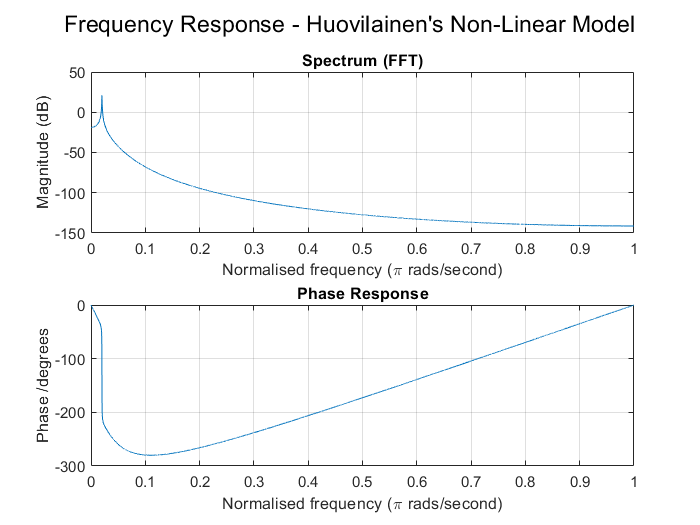

[magnt_nonlinear, phase_nonlinear] = deal(abs(fft(out_nonlinear)), angle(fft(out_nonlinear)));

figure;
sgtitle("Frequency Response - Huovilainen's Non-Linear Model")
subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        ( 10 * log( magnt_nonlinear(range_f) ) )...
        );
title("Spectrum (FFT)");
ylabel("Magnitude (dB)");
xlabel("Normalised frequency (\pi rads/second)");
grid on
subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        ( mod(( phase_nonlinear(range_f) * 180/pi ), -360) )...
        );
title("Phase Response");
ylabel("Phase /degrees");
xlabel("Normalised frequency (\pi rads/second)");
grid on

## Implementing the Automating Gain Stage v4.1

This 'version' allows the audio to be 'streamed' as buffers of 1024 samples per buffer (or dynamically allocated).

This should ensure smooth (relative) transition between the current, previous, and next buffers, and adapts v4.0.

From MovingRMS.m the formula used for calculating RMS is:


$$V_{rms}[k] = \sqrt{\frac{1}{N} \sum_{n=1}^{N} v_n[k]^2}$$


This can be seen here: [Energies | Free Full-Text | A Memory-Efficient True-RMS Estimator in a Limited-Resources Hardware | HTML (mdpi.com)](https://www.mdpi.com/1996-1073/12/9/1699/htm)

We now replicate the impulse here, albeit for two channels.

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
size_buffer = 44100;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];

size_window = size(in_audio, 1);
% Stores initial memory for initialisation
seq_mem_in = zeros((size_window - 1), 2);
seq_mem_out = zeros((size_window - 1), 2);
out_rms_log = zeros(0, 2);


NOTE: Poster feedback := compensate for delay at each point, ie find phase difference between each point?

Main Q: How to implement it for a software-based DSP? Specifically, audio plugin stream?

Investigate HOW.

IDEA:

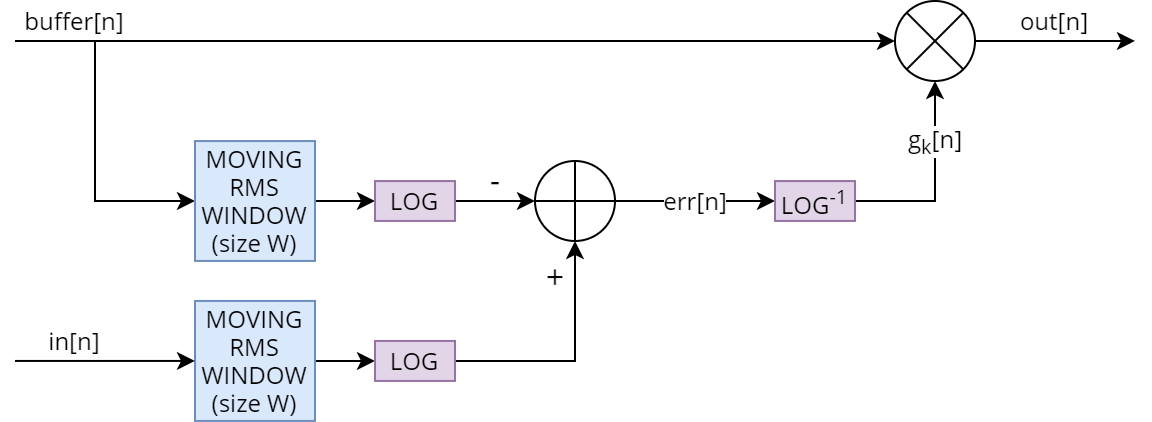

Program works in MATLAB since everything is sequential, therefore delay is expected. However, can we be a bit more specific?


tic;

% Find RMS of samples in current buffers & process memory
[rms_buffer_in, ~] = f_findRMS(in_audio, seq_mem_in);
[rms_buffer_out, ~] = f_findRMS(out_filtered, seq_mem_out);
err_rms = (20 * log10(rms_buffer_in)) - (20 * log10(rms_buffer_out));
out_rms_log = [out_rms_log; (out_filtered .* 10 .^ (err_rms ./ 20))];

toc

Elapsed time is 32.648511 seconds.


We can then plot the results below.

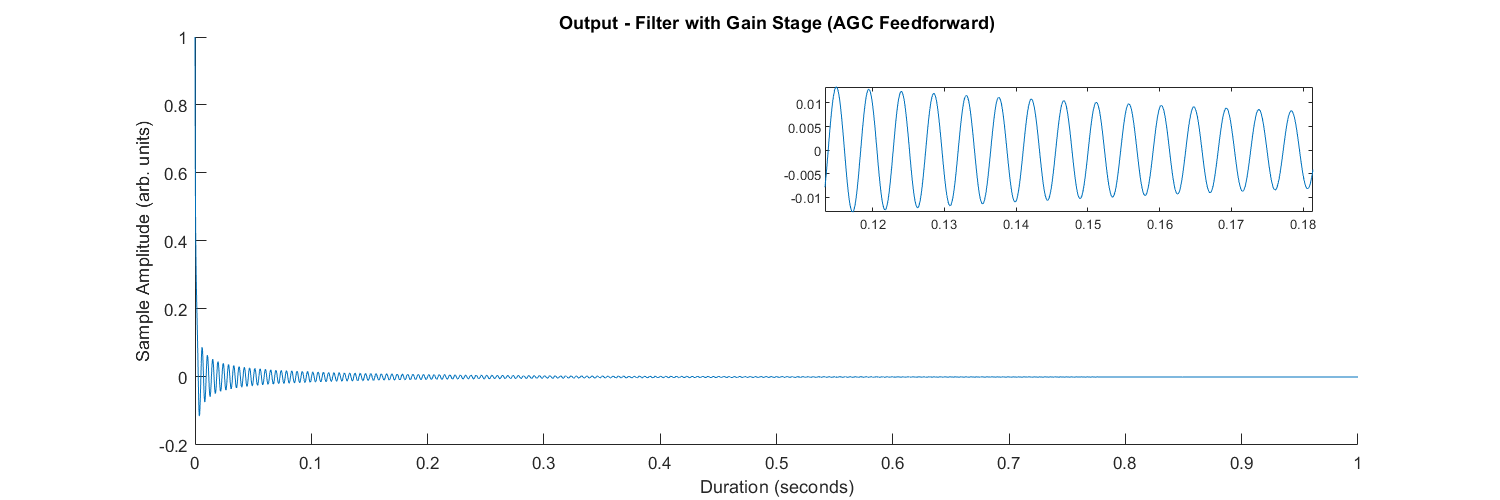

figure;
hold on;
plot(t(1:end-1), out_rms_log(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_rms_log(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

 [Automatic Gain Control - Techniques and Architectures for RF Receivers | Juan Pablo Alegre Pérez | Springer](https://www.springer.com/gp/book/9781461401667)

This version **works**! Now this has to be implemented into the plugin. (various improvements have been made, see original code)

Larger window size seems to give better resolution? Expected?

Running on REAPER & Audacity, given an impulse input, results in an oscillating-decay output at the same frequency as the cutoff frequency.

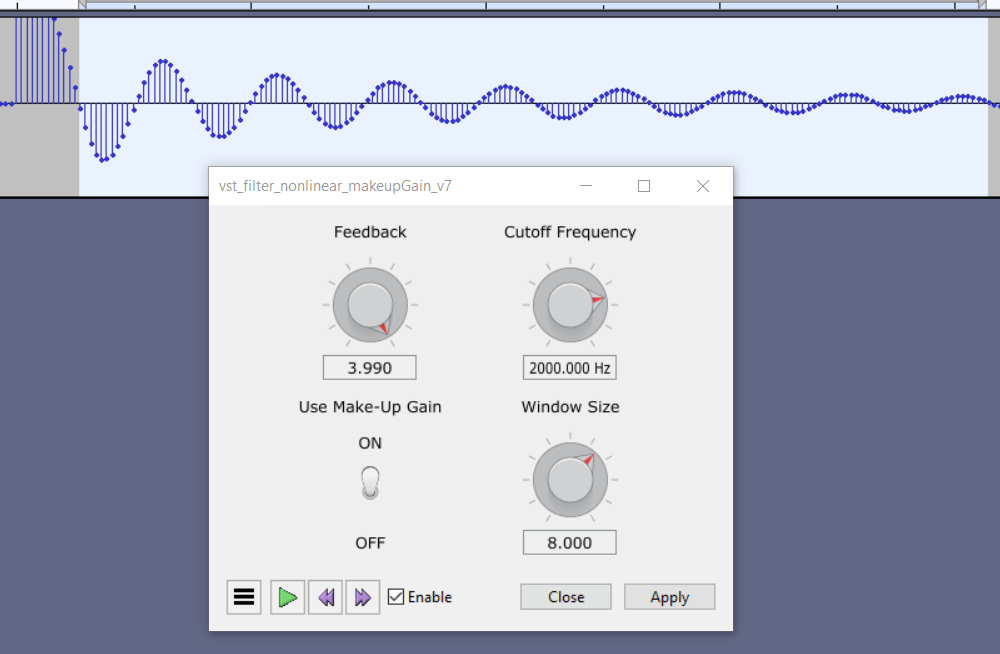

### Calculating signal energy

We can also find the energy of the input & output signal.


$$E = \sum_{n=-\infty}^{+\infty} x[n]^2 \equiv \sum_{n=0}^{N} x[n]^2 (N<\infty)$$


We can also divide the results by N to get a mean square value. This normalises the energy within the window. This is redundant, however, and could be ignored & use the regular sum instead.

e_in = mean(in_audio(:) .^ 2)

e_in = 2.2676e-05

e_outFiltered = mean(out_filtered(:) .^ 2)

e_outFiltered = 7.2092e-07

e_outRms = mean(out_rms_log(:) .^ 2)

e_outRms = 4.4605e-04

out_rms_TEST = out_rms_log;

NB: The moving average method fails, likely because the waveform in audio signals are mostly periodic, and finding an average over a large sample window would likely overtake a large number of cycles. Taking an average of this would result in a zero average. Hence, RMS is used instead.

The current method can be represented as the following diagram.

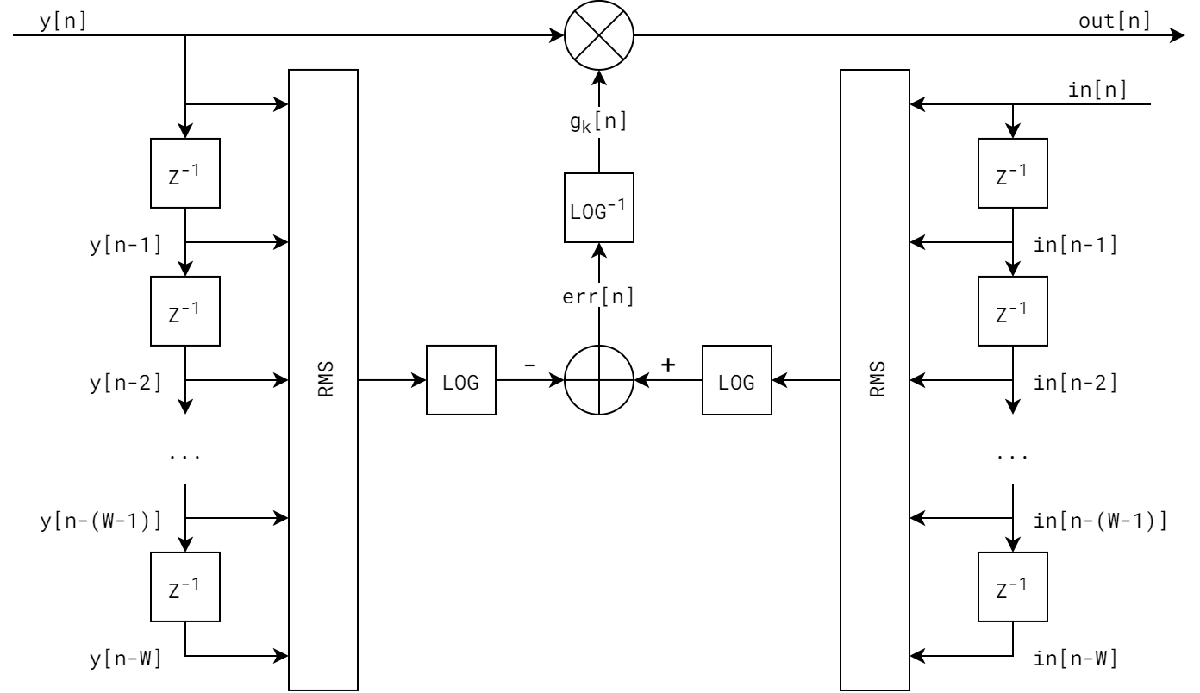

EDIT: After further discussions, given dB the RMS values would be subtracted (ie ref - out), so our feedforward AGC method is correct.

However to solidify this let us implement it in dB form. To be continued?

### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

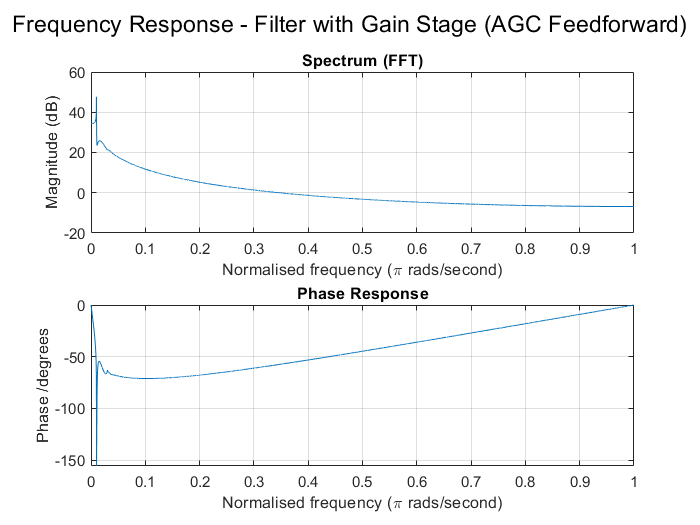

[magnt_out_rmsLog, phase_out_rmsLog] = deal(abs(fft(out_rms_log)), angle(fft(out_rms_log)));

figure;
sgtitle("Frequency Response - Filter with Gain Stage (AGC Feedforward)")
subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        ( 10 * log( magnt_out_rmsLog(range_f) ) )...
        );
title("Spectrum (FFT)");
ylabel("Magnitude (dB)");
xlabel("Normalised frequency (\pi rads/second)");
grid on
subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        ( mod(( phase_out_rmsLog(range_f) * 180/pi ), -360) )...
        );
title("Phase Response");
ylabel("Phase /degrees");
xlabel("Normalised frequency (\pi rads/second)");
grid on

## RMS Function investigation (bonus)

Although not required, it is worth investigating whether writing our own RMS calculation function would result in a smaller computation time, or otherwise, compared to the built-in DSP add-on function.

If less, then it is worth using our own implementation. (See original code for implementation)

It was found that my code is always faster than MATLAB's runtime. This might be due to MATLAB doing many checks in its code while my version just jumps right in.

This will be useful in the plugin real-time implementation.

## Implementing the Automating Gain Stage v5.1

This version implements the same as AG stage 4.1, however does so sample by sample.

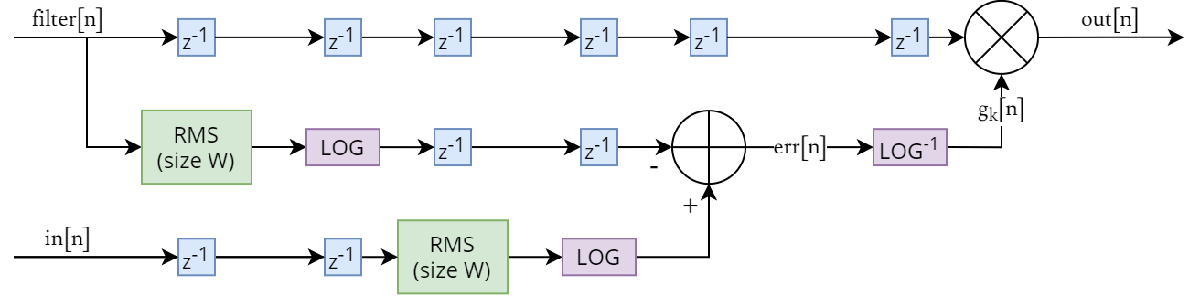

This version makes delays (accounted for in sequential processing) more noticeable.

The delays could potentially be reduced to much less with a direct-gain method, which eliminates the need for log-antilog conversions.

Pseudocode:

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];
% [in_audio, ~] = audioread("waterNight_original.wav");

% size_window = 1024 * 2^5; %22050; %size(in_audio, 1);
size_window = 44100;
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_rms_log = zeros(0, 2);

% For testing purposes
% nrg_input = zeros(0, 2);
% nrg_filtr = zeros(0, 2);
% nrg_outpt = zeros(0, 2);
% seq_gain = zeros(0, 2);

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    
    %%% 2) Calculate RMS values
    rms_filtr = [ rms(seq_proc_filtr(:, 1)), rms(seq_proc_filtr(:, 2)) ];
    rms_input = [ rms(seq_proc_input(:, 1)), rms(seq_proc_input(:, 2)) ];
    
    %%% 3) Converts RMS value to LOG
    log_rms_filtr = 20 * log10(rms_filtr);
    log_rms_input = 20 * log10(rms_input);
    
    %%% 4) Concerns sum block & antilog
    % Find the error value
    err_rms = log_rms_input - log_rms_filtr;
    % Converts err value to gain
    gain_corrector = 10 .^ (err_rms ./ 20);
    
    %%% 5) Apply gain to delayed filter output at sample n
    out_rms_log(end+1, :) = out_filtered(i_sample, :) .* gain_corrector;
    
    %%% 6) Adjust memory
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    seq_mem_input = seq_proc_input(2:end, :);
end
toc

Elapsed time is 35.185163 seconds.


We can then plot the results below.

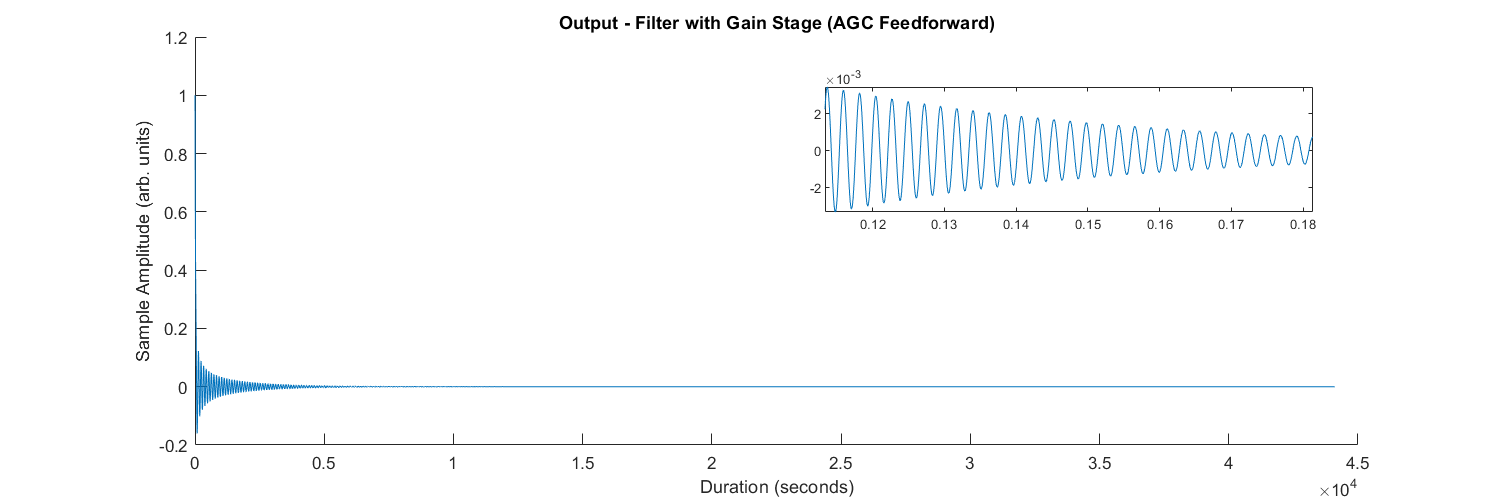

figure;
hold on;
% plot(t(1:end-1), out_rms_log(:, 1));
plot(out_rms_log(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_rms_log(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### Calculating signal energy

We can also find the energy of the input & output signal.

e_in = mean(in_audio(:, :) .^ 2)

e_in = 	1.0e+-4 *

    0.2268    0.2268


e_outFiltered = mean(out_filtered(:, :) .^ 2)

e_outFiltered = 	1.0e+-6 *

    0.7870    0.7870


e_outRms = mean(out_rms_log(:, :) .^ 2)

e_outRms = 	1.0e+-3 *

    0.3414    0.3414


### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

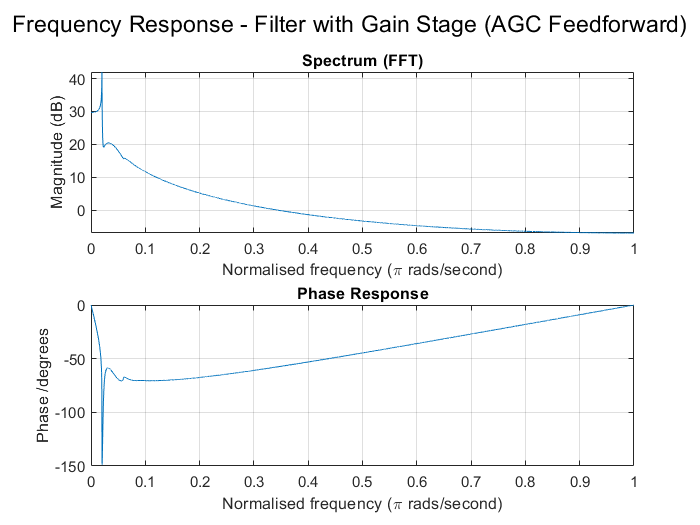

[magnt_out_rmsLog, phase_out_rmsLog] = deal(abs(fft(out_rms_log)), angle(fft(out_rms_log)));

figure;
sgtitle("Frequency Response - Filter with Gain Stage (AGC Feedforward)")
subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        ( 10 * log( magnt_out_rmsLog(range_f) ) )...
        );
title("Spectrum (FFT)");
ylabel("Magnitude (dB)");
xlabel("Normalised frequency (\pi rads/second)");
grid on
subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        ( mod(( phase_out_rmsLog(range_f) * 180/pi ), -360) )...
        );
        %( unwrap( phase_out_rmsLog(range_f) ) * 180/pi )...
        %);
title("Phase Response");
ylabel("Phase /degrees");
xlabel("Normalised frequency (\pi rads/second)");
grid on

## Implementing the Automating Gain Stage v5.1 - Shortcut Gain

This version exploits the mathematical equivalence of log-antilog relations & applies the gain directly.

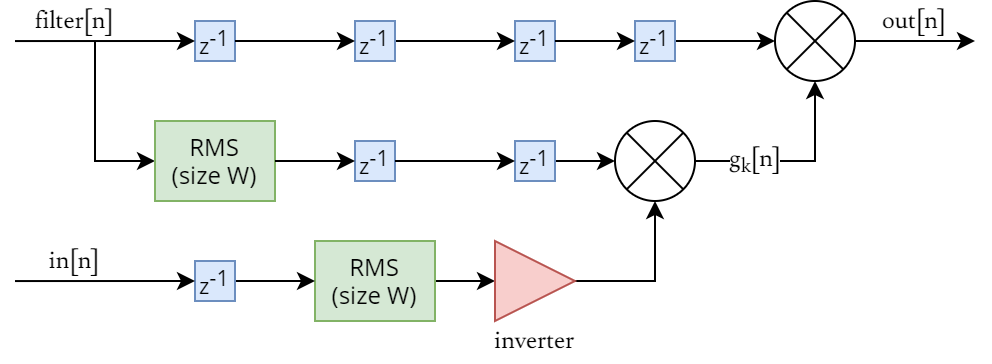

This version eliminates the need for log-antilog conversions, and reduces the number of delays required.

Pseudocode:

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];

size_window = size(in_audio, 1);
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_rms_gain = zeros(0, 2);

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Concerns filter output
    % Calculates RMS for filter output
    % Obtains sequence to use in calculating RMS
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    rms_filtr = [ rms(seq_proc_filtr(:, 1)), rms(seq_proc_filtr(:, 2)) ];
    
    %%% 2) Concerns audio input
    % Calculates RMS for audio input
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    rms_input = [ rms(seq_proc_input(:, 1)), rms(seq_proc_input(:, 2)) ];
    
    %%% 3) Concerns multiplier block
    % Since the log-antilog is mathematically equivalent
    % The RMS values can be divided directly
    gain_corrector = rms_input/rms_filtr;
    
    %%% 4) Apply gain to delayed filter output at sample n
    out_rms_gain = [out_rms_gain; (out_filtered(i_sample, :) .* gain_corrector)];
    
    %%% 5) Adjust memory
    % Shifts memory for filter output samples
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    % Shifts memory for audio input samples
    seq_mem_input = seq_proc_input(2:end, :);
    
end
toc

Elapsed time is 51.402639 seconds.


We can then plot the results below.

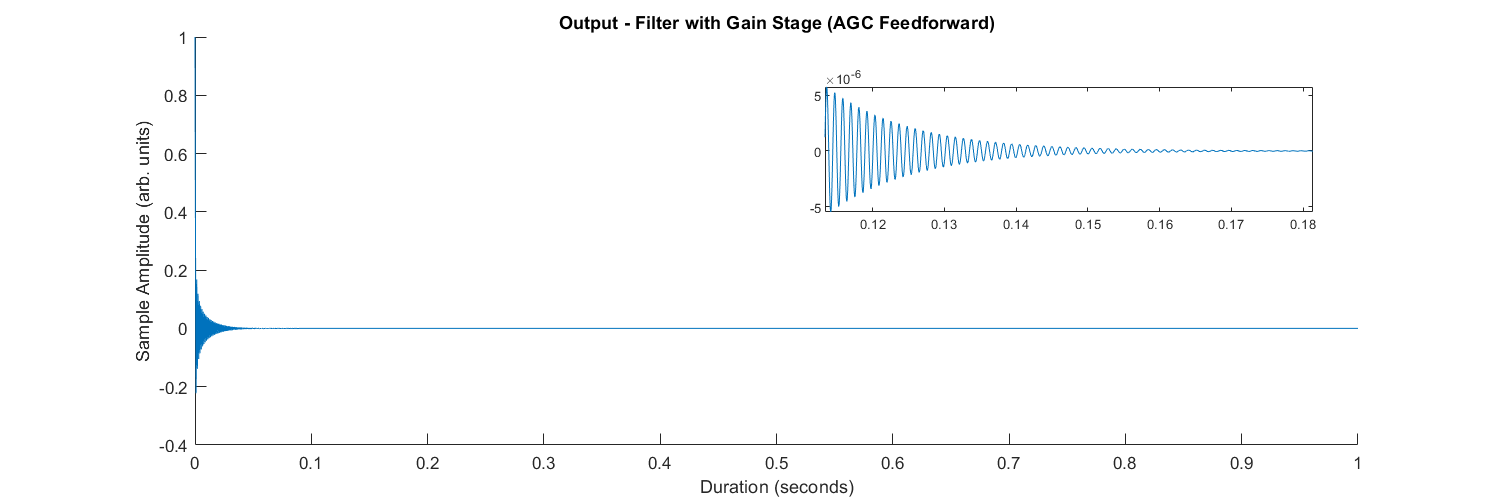

figure;
hold on;
plot(t(1:end-1), out_rms_gain(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_rms_gain(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### Calculating signal energy

We can also find the energy of the input & output signal.

e_gain_in = mean(in_audio(:, :) .^ 2)

e_gain_in = 	1.0e+-4 *

    0.2268    0.2268


e_gain_outFiltered = mean(out_filtered(:, :) .^ 2)

e_gain_outFiltered = 	1.0e+-6 *

    0.8483    0.8483


e_gain_outRms = mean(out_rms_gain(:, :) .^ 2)

e_gain_outRms = 	1.0e+-3 *

    0.2463    0.2463


### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

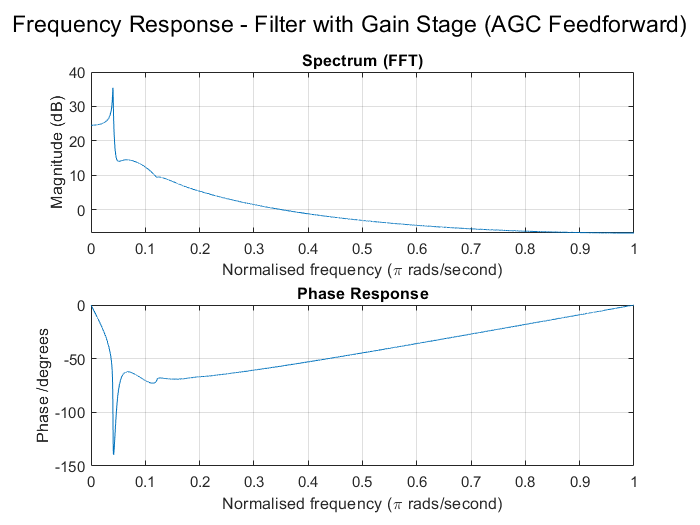

[magnt_out_rmsGain, phase_out_rmsGain] = deal(abs(fft(out_rms_gain)), angle(fft(out_rms_gain)));

figure;
sgtitle("Frequency Response - Filter with Gain Stage (AGC Feedforward)")
subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        ( 10 * log( magnt_out_rmsGain(range_f) ) )...
        );
title("Spectrum (FFT)");
ylabel("Magnitude (dB)");
xlabel("Normalised frequency (\pi rads/second)");
grid on
subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        ( mod(( phase_out_rmsGain(range_f) * 180/pi ), -360) )...
        );
title("Phase Response");
ylabel("Phase /degrees");
xlabel("Normalised frequency (\pi rads/second)");
grid on

Let us plot the spectogram as well.

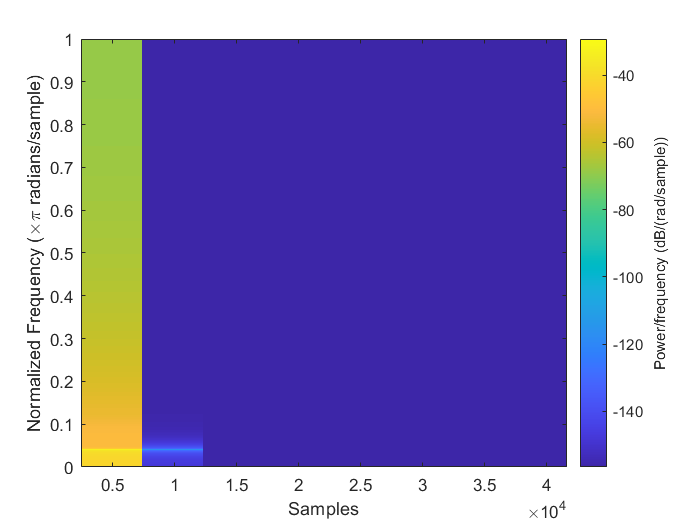

figure;
spectrogram(out_rms_gain(:, 1), 'yaxis')

## Implementing the Automating Gain Stage v6 - Perceived Loudness

This version implements the perceived loudness of an audio signal using the ISO 532-1.

[Perceived loudness of acoustic signal - MATLAB acousticLoudness - MathWorks United Kingdom](https://uk.mathworks.com/help/audio/ref/acousticloudness.html)

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];

sone_inAudio = acousticLoudness(in_audio, Fs,'SoundField','diffuse','TimeVarying', true)

sone_inAudio =          0         0
    4.0266    4.0266
   10.0192   10.0192
   12.4596   12.4596
   12.4026   12.4026
   11.2338   11.2338
    9.7621    9.7621
    8.3585    8.3585
    7.1754    7.1754
    6.2921    6.2921


sone_outFilt = acousticLoudness(out_filtered, Fs,'SoundField','diffuse','TimeVarying', true)

sone_outFilt =          0         0
         0         0
    0.0015    0.0015
    0.0249    0.0249
    0.0773    0.0773
    0.1469    0.1469
    0.2223    0.2223
    0.2999    0.2999
    0.3808    0.3808
    0.4676    0.4676


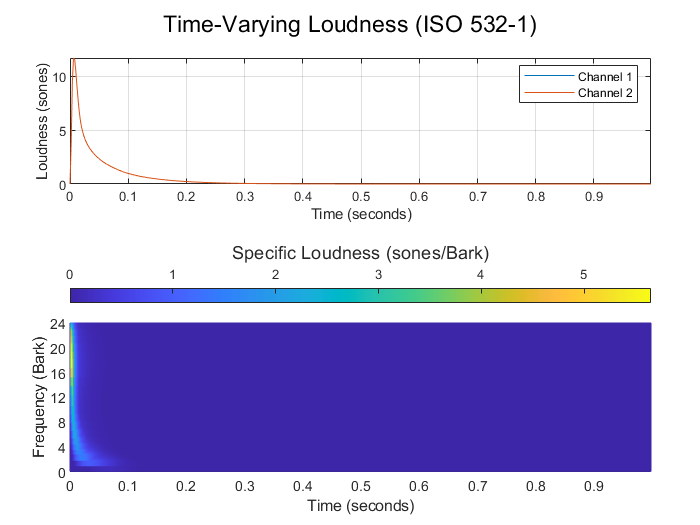

acousticLoudness(in_audio, Fs,'TimeVarying', true)

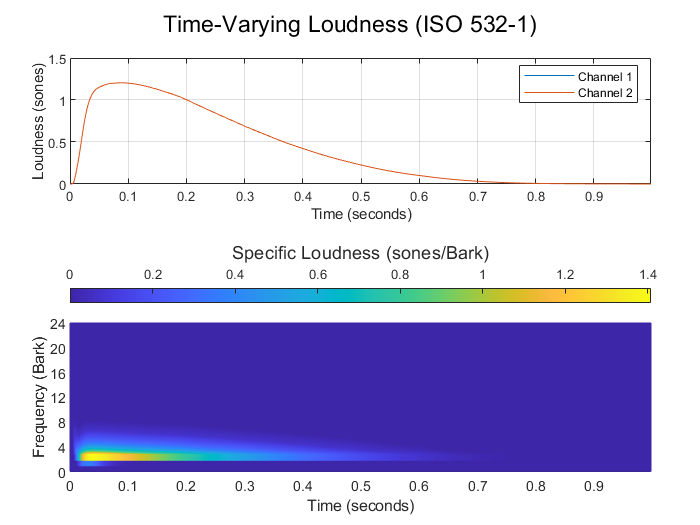

acousticLoudness(out_filtered, Fs,'TimeVarying', true)

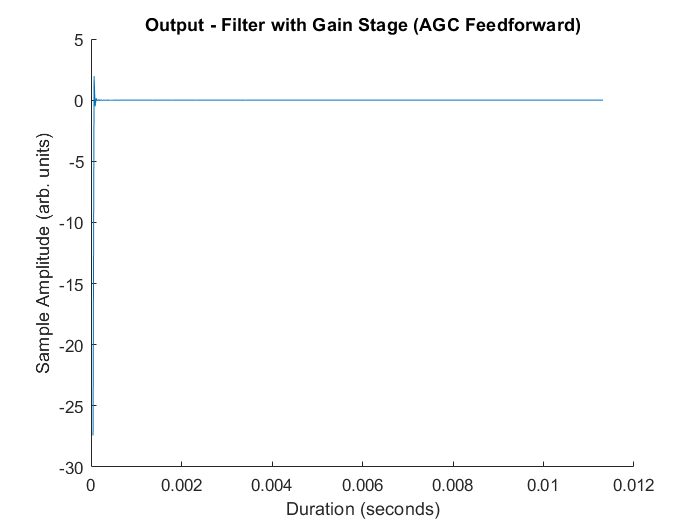

% Attempts at obtaining final signal
out_filtered_decimate = downsample(out_filtered, round(size(out_filtered, 1) / size(sone_outFilt, 1))); % Downsamples signal - obtaining sone obly obtains 500 points!
out_soneGain = out_filtered_decimate(1:500, :) .* (sone_inAudio ./ sone_outFilt);

figure;
hold on;
plot(t(1:500), out_soneGain(:, 1));
title("Output - Filter with Gain Stage (ISO 532-1)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");

This method doesn't quite work as it does not resemble the signal that we want.

## Implementing the Automating Gain Stage v7 - Frequency-based scaling

This version attempts to buffer a specific signal size, find the FFT, find the scaling factor, and apply the gain.

This method is similar to the RMS method, except that instead of finding the RMS in time domain, we look to frequency domain instead

% in_audio = zeros(44100, 2);
% in_audio(1, :) = 1;
% out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];
[in_audio, ~] = audioread("waterNight_original.wav");

size_window = 1024 * 2^5; %size(in_audio, 1);
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_fft_gain = zeros(0, 2);

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Concerns filter output
    % Calculates RMS for filter output
    % Obtains sequence to use in calculating RMS
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    % Gets FFT of current buffer
    fft_filtr_ch1 = fft(seq_proc_filtr(:, 1));
    fft_filtr_ch2 = fft(seq_proc_filtr(:, 2));
    % Calculates signal power of that chunk
    pwr_fft_filtr_ch1 = fft_filtr_ch1 .* conj(fft_filtr_ch1);
    pwr_fft_filtr_ch2 = fft_filtr_ch2 .* conj(fft_filtr_ch2);
    % Sums the power values together
    pwr_fft_filtr_ch1 = rms(pwr_fft_filtr_ch1);
    pwr_fft_filtr_ch2 = rms(pwr_fft_filtr_ch2);
    %fft_filtr = abs([ fft(seq_proc_filtr(:, 1)), fft(seq_proc_filtr(:, 2)) ]);
    %pwr_fft_filtr = pwr_fft_filtr_ch1 + pwr_fft_filtr_ch2;
    
    %%% 2) Concerns audio input
    % Calculates RMS for audio input
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    % Gets FFT of current buffer
    fft_input_ch1 = fft(seq_proc_input(:, 1));
    fft_input_ch2 = fft(seq_proc_input(:, 2));
    % Calculates signal power of that chunk
    pwr_fft_input_ch1 = fft_input_ch1 .* conj(fft_input_ch1);
    pwr_fft_input_ch2 = fft_input_ch2 .* conj(fft_input_ch2);
    % Sums the power values together
    pwr_fft_input_ch1 = sum(pwr_fft_input_ch1);
    pwr_fft_input_ch2 = sum(pwr_fft_input_ch2);
    %pwr_fft_input = pwr_fft_input_ch1 + pwr_fft_input_ch2;
    %fft_input = abs([ fft(seq_proc_input(:, 1)), fft(seq_proc_input(:, 2)) ]);
    
    %%% 3) Concerns multiplier block
    % Since the log-antilog is mathematically equivalent
    % The RMS values can be divided directly
    %gain_corrector_ch1 = ifft([fft_input(:, 1)./fft_filtr(:, 1)], size_window);
    %gain_corrector_ch2 = ifft([fft_input(:, 2)./fft_filtr(:, 2)], size_window);
    %gain_corrector = [rms(gain_corrector_ch1), rms(gain_corrector_ch2)];
    gain_corrector_ch1 = pwr_fft_input_ch1/pwr_fft_filtr_ch1;
    gain_corrector_ch2 = pwr_fft_input_ch2/pwr_fft_filtr_ch2;
    gain_corrector = [gain_corrector_ch1, gain_corrector_ch2];
    
    %%% 4) Apply gain to delayed filter output at sample n
    out_fft_gain = [out_fft_gain; (out_filtered(i_sample, :) .* gain_corrector)];
    
    %%% 5) Adjust memory
    % Shifts memory for filter output samples
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    % Shifts memory for audio input samples
    seq_mem_input = seq_proc_input(2:end, :);
    
end
toc

Elapsed time is 1381.622295 seconds.


We can then plot the results below.

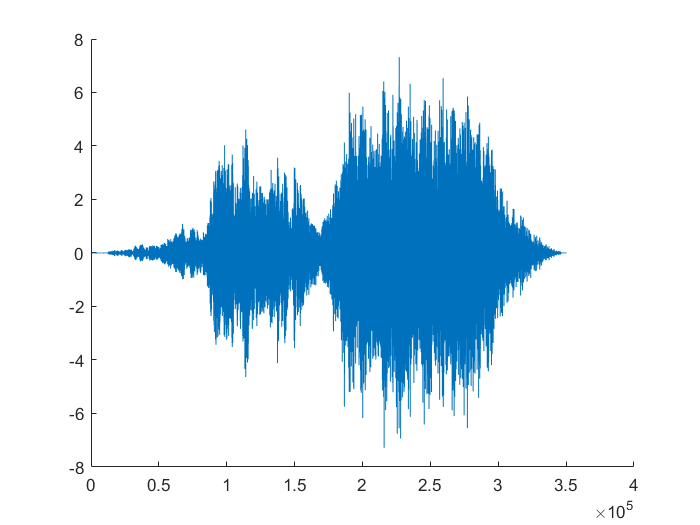

figure;
hold on;
plot(out_fft_gain(:, 1));

## Implementing the Automating Gain Stage v8 (derived from v5.1) [ON HOLD]

This version implements the same as AG stage 5.1, however in RMS calculations each sample also looks at values AFTER itself.

Pseudocode:

% in_audio = zeros(44100, 2);
% in_audio(1, :) = 1;
% out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];

in_audio = [12, 10, 8, 6, 4, 2];
in_audio = [in_audio', in_audio'];
out_filtered = [6, 5, 4, 3, 2, 1]

out_filtered =      6     5     4     3     2     1


out_filtered = [out_filtered', out_filtered'];

size_window = size(in_audio, 1);
% Sets initial memory as zeros
seq_mem_input
% Stores initial memory for initialisation
seq_mem_input = [zeros(((size_window / 2)), 2); in_audio(1:(size_window / 2), :)];
% seq_mem_input()
seq_mem_filtr = [zeros(((size_window / 2)), 2); out_filtered(1:(size_window / 2), :)];
out_rms_log = zeros(0, 2);
% Idea: check FFT on signal to measure nrg (same eq as time derived?)
% wave equation for mech wave
% check: is my system linear time-invarient?
% my thing might be LTI!
% eureka?: instead of rms, find signal nrg & find gain from there
% validate: for each buffer of in/out signal, calculate signal energy &
% compare gain

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Calculates RMS for filter output
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    rms_filtr = [ rms(seq_proc_filtr(:, 1)), rms(seq_proc_filtr(:, 2)) ];
    % Converts RMS value to LOG
    log_rms_filtr = 20 * log10(rms_filtr);
    
    %%% 2) Calculates RMS for audio input
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    rms_input = [ rms(seq_proc_input(:, 1)), rms(seq_proc_input(:, 2)) ];
    % Converts RMS value to LOG
    log_rms_input = 20 * log10(rms_input);
    
    %%% 3) Concerns sum block & antilog
    % Find the error value
    err_rms = log_rms_input - log_rms_filtr;
    % Converts err value to gain
    gain_corrector = 10 .^ (err_rms ./ 20);
    
    %%% 4) Apply gain to delayed filter output at sample n
    out_rms_log = [out_rms_log; (out_filtered(i_sample, :) .* gain_corrector)];
    
    %%% 5) Adjusts memory
    seq_mem_input = seq_proc_input(2:end, :);
    seq_mem_filtr = seq_proc_filtr(2:end, :);
end
toc

We can then plot the results below.

figure;
hold on;
plot(t(1:end-1), out_rms_log(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_rms_log(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

## Implementing the Automating Gain Stage v9

After further research, it was found that the algorithm used in v5.1 is actually compliant with ITU's method (see document).

This version attempts to apply K-weighting (or similar) to the signal before finding the RMS.

NOTE: This method might not be necessary; do we care about what we can hear & not the signal itself? This delves into psychoacoustics.

Pseudocode:

Main code:

in_audio = zeros(44100, 2);
in_audio(1, :) = 1;
out_filtered = [out_nonlinear(1:44100)' out_nonlinear(1:44100)'];
% [in_audio, ~] = audioread("waterNight_original.wav");

% size_window = 1024 * 2^5; %size(in_audio, 1);
size_window = 44100*2;
% Stores initial memory for initialisation
seq_mem_input = zeros((size_window - 1), 2);
seq_mem_filtr = zeros((size_window - 1), 2);
out_Lk_log = zeros(0, 2);

%%% Sets A-weighting filter
% weightFilt = weightingFilter("A-weighting");
% weightFilt = weightingFilter("C-weighting");
weightFilt = weightingFilter("K-weighting", Fs);


%%% TEST: Apply 'exponential' weight
arr_weight = linspace(0, 1, size_window);
arr_weight = [arr_weight; arr_weight]';

tic;
for i_sample = 1:length(in_audio)
    %%% 1) Obtain sequence of signals to process
    seq_proc_filtr = [seq_mem_filtr; out_filtered(i_sample, :)];
    seq_proc_input = [seq_mem_input; in_audio(i_sample, :)];
    
    %%% TEST: A-weighting stage
    seq_proc_aW_filtr = weightFilt(seq_proc_filtr);
    seq_proc_aW_input = weightFilt(seq_proc_input);
    
    seq_proc_aW_filtr = seq_proc_aW_filtr .* arr_weight;
    seq_proc_aW_input = seq_proc_aW_input .* arr_weight;
    
    %%% 2) Calculate RMS values
    Lk_filtr = [ rms(seq_proc_aW_filtr(:, 1)), rms(seq_proc_aW_filtr(:, 2)) ];
    Lk_input = [ rms(seq_proc_aW_input(:, 1)), rms(seq_proc_aW_input(:, 2)) ];
    
    %%% 3) Converts RMS value to LOG
    log_Lk_filtr = 10 * log10(Lk_filtr);
    log_Lk_input = 10 * log10(Lk_input);
    % Standard "ITU-R BS.1770-3" requires subtracting these LOG vals with –0.691
    % However, we intend to subtract the values together, so this becomes redundant
    
    %%% 4) Concerns sum block & antilog
    % Find the error value
    err_Lk = log_Lk_input - log_Lk_filtr;
    % Converts err value to gain
    gain_corrector = 10 .^ (err_Lk ./ 10);
    
    %%% 5) Apply gain to delayed filter output at sample n
    out_Lk_log(end+1, :) = out_filtered(i_sample, :) .* gain_corrector;
    
    %%% 6) Adjust memory
    seq_mem_filtr = seq_proc_filtr(2:end, :);
    seq_mem_input = seq_proc_input(2:end, :);
end
toc

Elapsed time is 2668.126019 seconds.


We can then plot the results below.

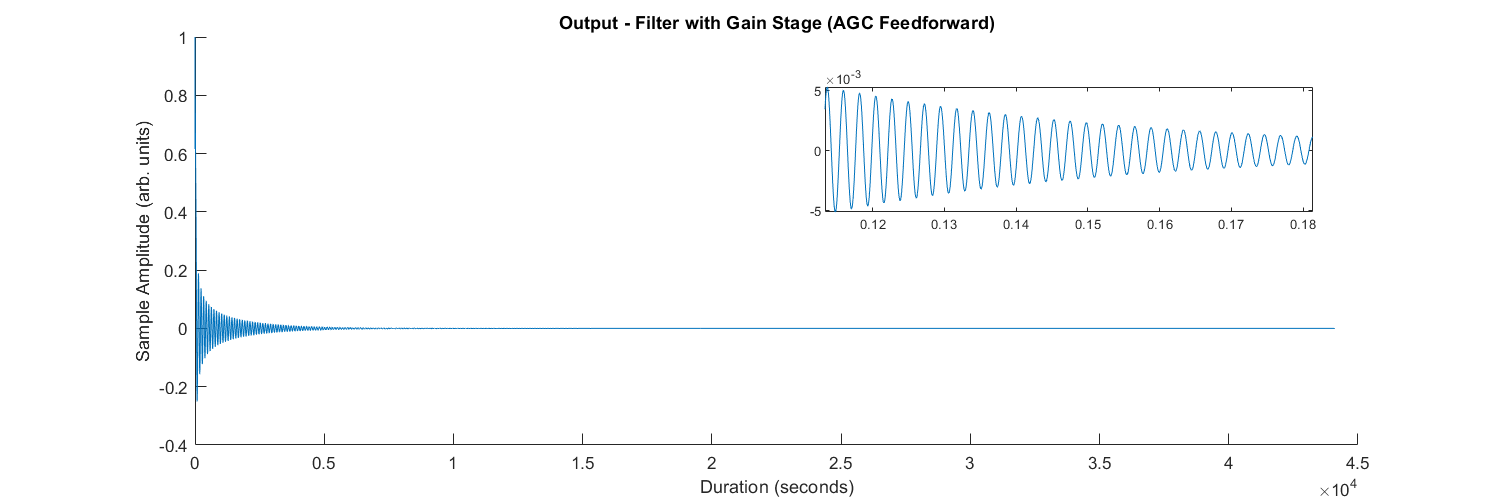

figure;
hold on;
plot(out_Lk_log(:, 1));
title("Output - Filter with Gain Stage (AGC Feedforward)");
xlabel("Duration (seconds)");
ylabel("Sample Amplitude (arb. units)");
axes('position', [0.55 0.575 0.325 0.25])
box on
plot(t(10000/2:16000/2), out_Lk_log(10000/2:16000/2))
axis tight
set(gcf, 'Position',  [0, 0, 1200, 400])

### Calculating signal energy

We can also find the energy of the input & output signal.

e_in = mean(in_audio(:, :) .^ 2)

e_in = 	1.0e+-4 *

    0.2268    0.2268


e_outFiltered = mean(out_filtered(:, :) .^ 2)

e_outFiltered = 	1.0e+-6 *

    0.7870    0.7870


e_outRms = mean(out_Lk_log(:, :) .^ 2)

e_outRms = 	1.0e+-3 *

    0.5740    0.5740


pwr_in = rms(in_audio(:, :))

pwr_in =     0.0048    0.0048


pwr_outFiltered = rms(out_filtered(:, :))

pwr_outFiltered = 	1.0e+-3 *

    0.8871    0.8871


pwr_outRms = rms(out_Lk_log(:, :))

pwr_outRms =     0.0240    0.0240


### Analyse Frequency Content

We can also analyse the frequency components in this output waveform

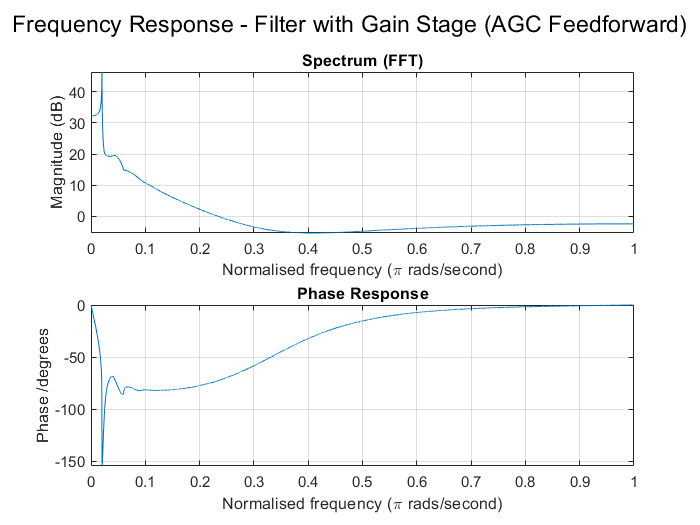

[magnt_out_Lk, phase_out_Lk] = deal(abs(fft(out_Lk_log)), angle(fft(out_Lk_log)));

figure;
sgtitle("Frequency Response - Filter with Gain Stage (AGC Feedforward)")
subplot(2, 1, 1);
plot(   (range_f_normalised / pi), ...
        ( 10 * log( magnt_out_Lk(range_f) ) )...
        );
title("Spectrum (FFT)");
ylabel("Magnitude (dB)");
xlabel("Normalised frequency (\pi rads/second)");
grid on
subplot(2, 1, 2);
plot(   (range_f_normalised / pi), ...
        ( mod(( phase_out_Lk(range_f) * 180/pi ), -360) )...
        );
        %( unwrap( phase_out_rmsLog(range_f) ) * 180/pi )...
        %);
title("Phase Response");
ylabel("Phase /degrees");
xlabel("Normalised frequency (\pi rads/second)");
grid on

## Functions

Define the models as functions below.

Function to calculate RMS over a set of values


$$V_{rms}[k] = \sqrt{\frac{1}{N} \sum_{n=1}^{N} v_n[k]^2}$$


function [out_rms, seq_memory] = f_findRMS(in_buffer, seq_memory)
% Stores RMS values per buffer
out_rms = zeros(0, 2);
% Goes through each symbol in frame
for i_sym = 1:length(in_buffer)
    % Obtains sequence for RMS finding
    seq_proc = [seq_memory; in_buffer(i_sym, :)];
    out_rms = [out_rms; [rms(seq_proc(:, 1)), rms(seq_proc(:, 2))]];
    seq_memory = seq_proc(2:end, :);
end
end

Function to calculate RMS - same as built-in function but faster

function out_rms_val = f_calculateRMS(in_arr)
% Calculates & returns the RMS value per formula
out_rms_val = sqrt((1/size(in_arr, 1)) * sum(in_arr .^ 2));
end

Function modelling Huovilainen's unit-delay model

function y = f_filter_linear_unit(y, in, g, k)
y(1) = y(1) + ( g * ( in - ( k * y(4) ) - y(1) ) );
y(2) = y(2) + ( g * ( y(1) - y(2) ) );
y(3) = y(3) + ( g * ( y(2) - y(3) ) );
y(4) = y(4) + ( g * ( y(3) - y(4) ) );
end

Function modelling Huovilainen's "unit-and-a-half" delay model

function [y, y_d2] = f_filter_linear_half(y, in, g, k, y_d2)
% Nonlinear implementation at y(4)+y_d2 uses previous value stored
% Initial previous value (ie y_d2) = 0
y(1) = y(1) + ( g * ( in - ( k * ( 0.5 * ( y(4) + y_d2 ) ) ) - y(1) ) );
y(2) = y(2) + ( g * ( y(1) - y(2) ) );
y(3) = y(3) + ( g * ( y(2) - y(3) ) );
y_d2 = y(4);
y(4) = y(4) + ( g * ( y(3) - y(4) ) );
end

Function modelling Huovilainen's non-linear model

function [y, y_d2] = f_filter_nonlinear(y, in, g, k, y_d2)
% Nonlinear implementation at y(4)+y_d2 uses previous value stored
% Initial previous value (ie y_d2) = 0
y(1) = y(1) + ( g * ( tanh( in - ( k * ( 0.5 * ( y(4) + y_d2 ) ) ) ) - tanh( y(1) ) ) );
y(2) = y(2) + ( g * ( tanh( y(1) ) - tanh( y(2) ) ) );
y(3) = y(3) + ( g * ( tanh( y(2) ) - tanh( y(3) ) ) );
y_d2 = y(4);
y(4) = y(4) + ( g * ( tanh( y(3) ) - tanh( y(4) ) ) );
end

Function as entry point for models

function out = f_runFilter(in, tDuration, Fs, g, k, mode)
y = zeros(1, 4);
% 1/Fs == Ts
% Recall n=t/Ts == t*Fs
Ts = 1/Fs;
% NB: Sample index 1 starts at Ts
index_start = Ts * Fs; % Index 1
% NB: Verbosity for clarification
index_end = tDuration * Fs;
% Given duration of 1s
switch mode
    case "linear_unit"
        % 1:(Fs) - code is operating in time domain
        % So, change it to smth more logical!
        for index = index_start:1:index_end
            y = f_filter_linear_unit(y, in(index), g, k);
            out(index) = y(4);
        end
    case "linear_half"
        y_d2 = 0; % equivalent to y_d^{n-2} per H's analysis
        % See Daly's (3.6)
        for index = index_start:1:index_end
            [y, y_d2] = f_filter_linear_half(y, in(index), g, k, y_d2);
            out(index) = y(4);
        end
    case "nonlinear"
        y_d2 = 0; % equivalent to y_d^{n-2} per H's analysis
        % See Daly's (3.6)
        for index = index_start:1:index_end
            [y, y_d2] = f_filter_nonlinear(y, in(index), g, k, y_d2);
            out(index) = y(4);
        end
end
end

Function to calculate coefficient weight.

function coefWeight = f_coefWeight(Fc, Fs)
coefWeight = 1 - exp( (-2 * pi) * ( Fc / Fs ) );
end

Function to obtain lookup gain from the lookup table.

Function containing the bilinear interpolation algorithm.